% Load the data from the Excel file
file_name = 'mpc_mes.xlsx';
sheet_name = 'Run 3_ mcb_pmsm_foc_host_model_';
data = readtable(file_name, 'Sheet', sheet_name);


% Extract relevant columns
time = data.time;
speed_ref = data.Subsystem_2; % Subsystem:2 as Speed_Ref
speed_fb = data.Subsystem_3; % Subsystem:3 as Speed_fb

% Calculate system metrics
step_input = max(speed_ref);
steady_state_value = mean(speed_fb(end-9:end)); % Last 10 samples
steady_state_error = abs(step_input - steady_state_value);

% Initialize metrics
overshoot = 0;
rise_time = 0;
settling_time = 0;
tolerance = 0.02; % 2% tolerance

% Calculate overshoot
peak_value = max(speed_fb);
if steady_state_value ~= 0
    overshoot = ((peak_value - steady_state_value) / steady_state_value) * 100;
else
    overshoot = Inf; % Handle division by zero
end

% Calculate rise time (10% to 90% of steady state value)
rise_start = steady_state_value * 0.1;
rise_end = steady_state_value * 0.9;
rise_start_index = find(speed_fb >= rise_start, 1, 'first');
rise_end_index = find(speed_fb >= rise_end, 1, 'first');
if ~isempty(rise_start_index) && ~isempty(rise_end_index)
    rise_time = time(rise_end_index) - time(rise_start_index);
else
    rise_time = NaN; % Handle cases where rise time cannot be determined
end

% Calculate settling time (within tolerance of steady state value)
upper_bound = steady_state_value * (1 + tolerance);
lower_bound = steady_state_value * (1 - tolerance);
out_of_bounds_indices = find(speed_fb > upper_bound | speed_fb < lower_bound);
if ~isempty(out_of_bounds_indices)
    settling_time = time(out_of_bounds_indices(end));
else
    settling_time = time(end); % Assume system is settled at the end
end

% Display results
fprintf('Step Input: %.2f\n', step_input);

Step Input: 1500.00


fprintf('Steady-State Value: %.2f\n', steady_state_value);

Steady-State Value: 0.00


fprintf('Steady-State Error: %.2f\n', steady_state_error);

Steady-State Error: 1500.00


fprintf('Overshoot: %.2f%%\n', overshoot);

Overshoot: Inf%


fprintf('Rise Time: %.4f seconds\n', rise_time);

Rise Time: 0.0000 seconds


fprintf('Settling Time: %.4f seconds\n', settling_time);

Settling Time: 8.3400 seconds


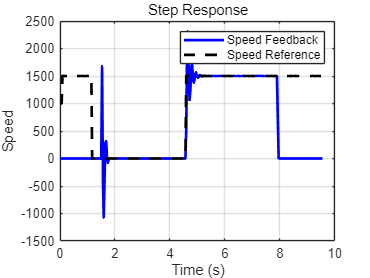


% Plot response curves
figure;
plot(time, speed_fb, 'b-', 'LineWidth', 2);
hold on;
plot(time, speed_ref, 'k--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Speed');
title('Step Response');
grid on;
legend('Speed Feedback', 'Speed Reference');

% Load the data from the Excel file
file_name = 'pi_mes.xlsx';
sheet_name = 'Run 2_ mcb_pmsm_foc_host_model_';
data = readtable(file_name, 'Sheet', sheet_name);


% Extract relevant columns
time = data.time;
speed_ref = data.Subsystem_2; % Subsystem:2 as Speed_Ref
speed_fb = data.Subsystem_3; % Subsystem:3 as Speed_fb

% Calculate system metrics
step_input = max(speed_ref);
steady_state_value = mean(speed_fb(end-9:end)); % Last 10 samples
steady_state_error = abs(step_input - steady_state_value);

% Initialize metrics
overshoot = 0;
rise_time = 0;
settling_time = 0;
tolerance = 0.02; % 2% tolerance

% Calculate overshoot
peak_value = max(speed_fb);
if steady_state_value ~= 0
    overshoot = ((peak_value - steady_state_value) / steady_state_value) * 100;
else
    overshoot = Inf; % Handle division by zero
end

% Calculate rise time (10% to 90% of steady state value)
rise_start = steady_state_value * 0.1;
rise_end = steady_state_value * 0.9;
rise_start_index = find(speed_fb >= rise_start, 1, 'first');
rise_end_index = find(speed_fb >= rise_end, 1, 'first');
if ~isempty(rise_start_index) && ~isempty(rise_end_index)
    rise_time = time(rise_end_index) - time(rise_start_index);
else
    rise_time = NaN; % Handle cases where rise time cannot be determined
end

% Calculate settling time (within tolerance of steady state value)
upper_bound = steady_state_value * (1 + tolerance);
lower_bound = steady_state_value * (1 - tolerance);
out_of_bounds_indices = find(speed_fb > upper_bound | speed_fb < lower_bound);
if ~isempty(out_of_bounds_indices)
    settling_time = time(out_of_bounds_indices(end));
else
    settling_time = time(end); % Assume system is settled at the end
end

% Display results
fprintf('Step Input: %.2f\n', step_input);

Step Input: 16428.00


fprintf('Steady-State Value: %.2f\n', steady_state_value);

Steady-State Value: 0.00


fprintf('Steady-State Error: %.2f\n', steady_state_error);

Steady-State Error: 16428.00


fprintf('Overshoot: %.2f%%\n', overshoot);

Overshoot: Inf%


fprintf('Rise Time: %.4f seconds\n', rise_time);

Rise Time: 0.0000 seconds


fprintf('Settling Time: %.4f seconds\n', settling_time);

Settling Time: 20.7300 seconds


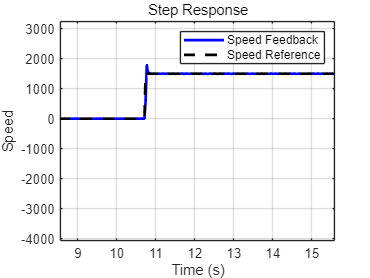


% Plot response curves
figure;
plot(time, speed_fb, 'b-', 'LineWidth', 2);
hold on;
plot(time, speed_ref, 'k--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Speed');
title('Step Response');
grid on;
legend('Speed Feedback', 'Speed Reference');